# Identificazione Closed-Loop

Identificazione del modello di ciascun giunto in anello chiuso.

Ciascun giunto è **eccitato singolarmente** con un segnale di coppia, mentre un **controllore poco aggressivo** applica una coppia sufficiente a mantenere i giunti **nell'intorno della posizione iniziale**. I modelli stimati, quindi, hanno la massima validità per piccoli scostamenti dalla posizione di zero.

I modelli ricavati hanno come **input** la *coppia* fornita al motore e come **output** la *velocità* dell'albero.

Eccitando ciascun motore singolarmente, il sistema viene scomposto in **due sistemi SISO** che si influenzano mutualmente; tale influenza viene trattata come **disturbo causato da un sistema sull'altro**, che necessita di compensazione.

clear; close all; clc;

Opzione per evitare la molteplicità di 360° nella fase nei diagrammi di Bode

bode_opts = bodeoptions('cstprefs');
bode_opts.PhaseWrapping = 'on';

## Definizione sistema controllato

Creazione sistema e salvataggio tempo di campionamento

model_initialization;

Accelerazione massima e Rest Time

cs.setMaxAcceleration(15);
cs.setRestTime(0.1);

*Directory* per salvataggio o caricamento **dati di simulazione**

simulation.author = 'CL_M';     Nprova = 22;
simulationName = strcat(simulation.author,'_simulation_',num2str(Nprova));
simulationDirectory = strcat('.\simulations\identification\data\',simulationName);
simFigDirectory = strcat('.\simulations\identification\figures\',simulationName);

*Directory* per salvataggio o caricamento **modello stimato**

simulation.author = 'CL_M';     Nprova = 22;
modelName = strcat(simulation.author,'_model_', num2str(Nprova));
directoryModel = strcat('.\estimated_models\data\',modelName);
modelFigDirectory = strcat('.\estimated_models\figures\',modelName);

## Definizione segnale eccitante e riferimento per il controllore

### Parametri

Definizione dei parametri che possono essere tarati per variare il segnale eccitante.

- Calcoliamo la **massima pulsazione ammissibile** per il segnale. Deve essere al massimo la metà della pulsazione di campionamento al fine di evitare fenomeni di *aliasing* (*Teorema di Shannon*).

- Estraiamo inoltre dal sistema la **massima coppia** che ciascun motore può erogare.

w_max = pi/st           % rad/s     (Fs=1/Ts, Ws=2*pi/Ts, 0.5*Ws=pi/Ts)

w_max = 3.1416e+03

umax = system.getUMax   % Nm

umax =    150
   150


Chirp

w0_chirp = 10;      w1_chirp = w_max;      % chirp su tutto il range frequenziale
w0b_chirp = 80;     w1b_chirp = 400;     % chirp concentrato nella zona della risonanza
w0c_chirp = 50;     w1c_chirp = 1000;     % chirp aggiuntivo (opzionale)
ampiezza_chirp = 90;

Portante

w_portante = w0_chirp/20;   % la portante è circa una decade più lenta del chirp
ampiezza_portante = 50;
T_portante = 2*pi/w_portante;

durata_simulazione = 1.1*T_portante; % secondi

### Portante

Definizione del segnale portante, che ha la funzione di fornire un segnale eccitante che permetta di evitare eccessivi attraversamenti dello zero per il segnale di velocità.

t = (0:st:durata_simulazione)';
portante = ampiezza_portante*sin(w_portante*t);

### Chirp

Aggiunti due segnali *chirp* per infittire l'indagine della zona di interesse (i tre segnali *chirp* sono sfasati di 45°).

chirp_wide = chirp(t,w0_chirp/2/pi,t(end),w1_chirp/2/pi,'logarithmic',90);          % 90° per iniziare come un seno
chirp_narrow1 = chirp(t,w0b_chirp/2/pi,t(end),w1b_chirp/2/pi,'logarithmic',135);
chirp_narrow2 = chirp(t,w0c_chirp/2/pi,t(end),w1c_chirp/2/pi,'logarithmic',180);

% Chirp complessivo scalato dell'ampiezza desiderata
chirp_total = (chirp_wide + chirp_narrow1 + chirp_narrow2)/max(chirp_wide + chirp_narrow1 + chirp_narrow2);
chirpSignal = ampiezza_chirp*chirp_total;

### Somma dei segnali

input_signal = portante + chirpSignal;

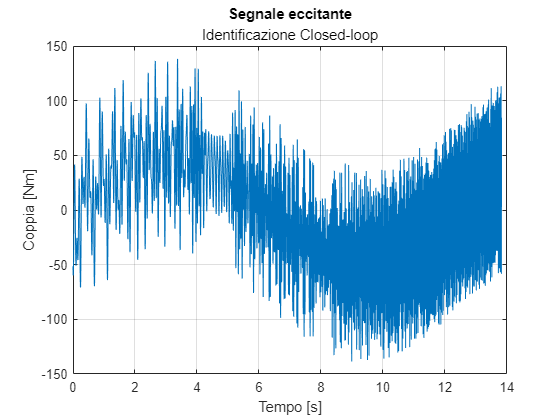

fig_inputSignal = figure;
plot(t,input_signal);
xlabel('Tempo [s]'); ylabel('Coppia [Nm]'); title('Segnale eccitante'); subtitle('Identificazione Closed-loop'); grid on;


% Salvataggio della figura
% set(gcf,'renderer','painters')
% exportgraphics(gcf,'.\presentation\identification\segnale_eccitante_id_CL.emf')

### Segnale di riferimento

Nullo per entrambi i giunti.

reference = zeros(length(t),system.getOutputNumber);

## Selezione sottosistemi di cui eseguire l'identificazione

Il segnale eccitante viene iniettato solo nei giunti la cui *checkbox* è spuntata.

joint1 = false;    joint2 = true;

if joint1 && ~joint2
    control_action = [input_signal zeros(length(input_signal),1)];

elseif joint2 && ~joint1
    control_action = [zeros(length(input_signal),1) input_signal];

elseif joint1 && joint2
    control_action = [input_signal input_signal];
    warning('Eccitare un giunto alla volta per una corretta identificazione.')

else
    error('Selezionare almeno un giunto.')
end

### Calcolo durata indicativa della simulazione

durata_teorica = seconds(durata_simulazione); % debug
durata_teorica.Format = 'hh:mm:ss';
display(durata_teorica)

durata_teorica = duration
   00:00:13


sample_computation_time = 0.015; % stimato empiricamente su 100 run
durata_reale = seconds(length(t)*sample_computation_time);
durata_reale.Format = 'hh:mm:ss';
display(durata_reale)

durata_reale = duration
   00:03:27


## Controllore

Un **controllore di tipo PD**, tarato in modo poco aggressivo, permette di seguire il riferimento nullo di posizione. I parametri riferiti al **giunto in fase di identificazione** saranno *tarati in modo molto blando*, affinchè il link possa comunque oscillare in una maggiore porzione dello spazio di lavoro, mentre **l'altro giunto** è tenuto nell'intorno della posizione di zero grazie ad una *taratura più aggressiva*.

if (joint1)
    Kp_values =  [1 1000];    Kv_values =  [5 50];

else % joint2
    Kp_values =  [1000 10];    Kv_values =  [50 0.5];
end

controller = SimpleScaraController(st,Kp_values,Kv_values);
cs.setController(controller);

## Simulazione sistema

checkSimulation = false;    checkLoadingData = true;

if checkSimulation && ~checkLoadingData

    f = waitbar(0,'0','Name','Simulazione - Identificazione',...
                'CreateCancelBtn','setappdata(gcbf,''canceling'',1)');
    setappdata(f,'canceling',0);

%     execution_time = zeros(length(t),1); % debug

    cs.initialize % SCARA riposizionato nella configurazione di riposo iniziale

    for idx=1:length(t)
        % tic
        
        % Bottone Cancel per arrestare la simulazione senza eliminare i dati parziali
        if getappdata(f,'canceling')
            break
        end
        
        % step: simulazione sistema in anello chiuso
        % PARAMETRI
        % ingresso 1: riferimento
        % ingresso 2: azione sul carico come segnale eccitante (a valle del controllore)
        [process_output(idx,:),control_action(idx,:),tt(idx,1)]=cs.step(reference(idx,:)',control_action(idx,:)'); 

        % Aggiornamento waitbar
        percent_progress = idx/length(t)*100;
        waitbar(percent_progress/100,f,sprintf('%.2f %%',percent_progress))

        % execution_time(idx) = toc; % debug
    end

    beep

    delete(f)

%     disp('Tempo di esecuzione medio di una singola simulazione')
%     mean_execution_time = mean(execution_time) % debug

elseif checkLoadingData && ~checkSimulation
    load(simulationDirectory);

else
    error('Selezionare una delle due opzioni.')
end

## Calcolo funzione di trasferimento coppia-velocità

Calcolo e diagramma di Bode della risposta in frequenza. Le frequenze iniziali e finali per i segnali eccitanti sono indicate da linee verticali.

### Giunto 1

if (joint1)
    identification_joint1 = iddata(process_output(:,3),control_action(1:length(tt),1),st);
    identification_joint1.OutputName = 'vel1'; identification_joint1.InputName = 'torque1';
    
    freq_resp_ident_joint1 = spafdr(identification_joint1);
    
    fig_j1 = figure;
    bode(freq_resp_ident_joint1,'.-',bode_opts)
    grid on
    hold on
    plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
    plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
    plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
    hold off
    
    % Titolo ed etichette assi personalizzate
    axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
    ha = get(axes(3),'title'); ha.String = 'Input: Coppia [Nm] - Output: Velocità [rad/s]';
    ha = get(axes(1),'title'); ha.String = 'Funzione di trasferimento sperimentale - Giunto 1';

    h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
    h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
    x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
    x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\identification\CL_ident_joint1.emf')
end

### Giunto 2

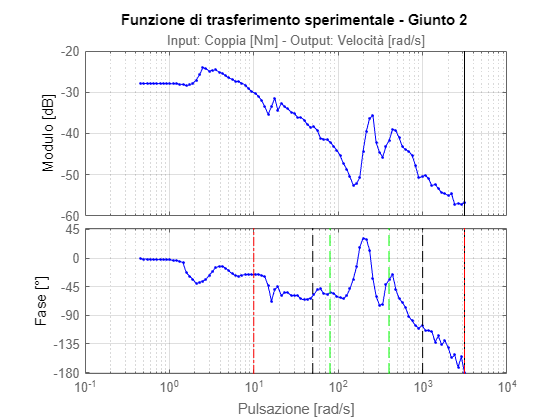

if (joint2)
    identification_joint2 = iddata(process_output(:,4),control_action(1:length(tt),2),st);
    identification_joint2.OutputName = 'vel2'; identification_joint2.InputName = 'torque2';
    
    freq_resp_ident_joint2 = spafdr(identification_joint2);

    fig_j2 = figure;
    bode(freq_resp_ident_joint2,'.-',bode_opts)
    grid on
    hold on
    plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
    plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
    plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
    hold off

    % Titolo ed etichette assi personalizzate
    axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
    ha = get(axes(3),'title'); ha.String = 'Input: Coppia [Nm] - Output: Velocità [rad/s]';
    ha = get(axes(1),'title'); ha.String = 'Funzione di trasferimento sperimentale - Giunto 2';

    h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
    h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
    x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
    x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\identification\CL_ident_joint2.emf')
end

## Grafico dei risultati

% system.getInputName
% system.getOutputName
pos1=process_output(:,1); pos2=process_output(:,2);
vel1=process_output(:,3); vel2=process_output(:,4);
tau1=control_action(:,1); tau2=control_action(:,2);

Saturazione dei samples di coppia effettivamente applicati durante la simulazione (anche in caso questa sia stata arrestata prima del suo completamento)

actual_tau1 = min(max(tau1(1:length(tt)),-umax(1)),umax(1));
actual_tau2 = min(max(tau2(1:length(tt)),-umax(2)),umax(2));

Plot dei segnali su assi con uguale scala per i due giunti, in modo da verificare l'entità della risposta al segnale eccitante e l'azione del controllore sul giunto non eccitato.

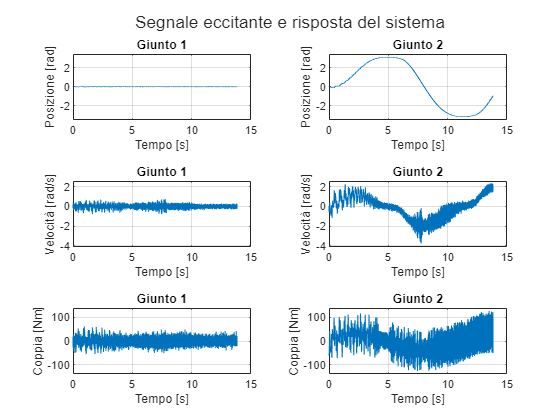

fig_res = figure;
tl = tiledlayout(3,2);

% Posizione
nexttile; plot(tt,pos1); title('Giunto 1');
grid on; xlabel('Tempo [s]'); ylabel('Posizione [rad]'); ylim([1.1*min([pos1;pos2]) 1.1*max([pos1;pos2])])

nexttile; plot(tt,pos2); title('Giunto 2');
grid on; xlabel('Tempo [s]'); ylabel('Posizione [rad]'); ylim([1.1*min([pos1;pos2]) 1.1*max([pos1;pos2])])

% Velocità
nexttile; plot(tt,vel1); title('Giunto 1'); 
grid on; xlabel('Tempo [s]'); ylabel('Velocità [rad/s]'); ylim([1.1*min([vel1;vel2]) 1.1*max([vel1;vel2])])

nexttile; plot(tt,vel2); title('Giunto 2');
grid on; xlabel('Tempo [s]'); ylabel('Velocità [rad/s]'); ylim([1.1*min([vel1;vel2]) 1.1*max([vel1;vel2])])

% Coppia
nexttile; plot(tt,actual_tau1); title('Giunto 1');
grid on; xlabel('Tempo [s]'); ylabel('Coppia [Nm]');
ylim([1.1*min([actual_tau1;actual_tau2]) 1.1*max([actual_tau1;actual_tau2])])

nexttile; plot(tt,actual_tau2);  title('Giunto 2');
grid on; xlabel('Tempo [s]'); ylabel('Coppia [Nm]');
ylim([1.1*min([actual_tau1;actual_tau2]) 1.1*max([actual_tau1;actual_tau2])])

title(tl,'Segnale eccitante e risposta del sistema')

% Salvataggio della figura
% set(gcf,'renderer','painters')
% exportgraphics(gcf,'.\presentation\identification\segnali_id_CL.emf')

## Salvataggio simulazione

if checkSimulation
    % Salvataggio dati di simulazione
    simulation.description = '3xchirp + portante - j1';
    simulation.w0chirp = w0_chirp;
    simulation.w1chirp = w1_chirp;
    simulation.wportante = w_portante;
    simulation.ampiezza_chirp = ampiezza_chirp;
    simulation.ampiezza_portante = ampiezza_portante;
    simulation.durata_simulazione = durata_simulazione;
    simulation.control_action = control_action;
    simulation.process_output = process_output;
    simulation.tt = tt;
    simulation.joint1 = joint1;
    simulation.joint2 = joint2;
    simulation.durata_teorica = durata_teorica;
    simulation.durata_reale = durata_reale;
    simulation.Kp_values = Kp_values;
    simulation.Kv_values = Kv_values;
    
    save(simulationDirectory,'-struct','simulation')

    % Salvataggio figure
    if (joint1)
        savefig(fig_j1,strcat(simFigDirectory,'_j1'))
    end
    if (joint2)
        savefig(fig_j2,strcat(simFigDirectory,'_j2'))
    end
    savefig(fig_res,strcat(simFigDirectory,'_res'))
    savefig(fig_inputSignal,strcat(simFigDirectory,'_inputSignal'))
end

## Stima del modello

Fitting del modello continuo e discreto sulla FRF sperimentale. E' possibile sia stimare un nuovo modello, sia caricarne uno già calcolato.

Specificando il range frequenziale, il modello viene fittato in quella regione: questo garantisce la migliore stima possibile del picco di risonanza, che è l'elemento a cui siamo maggiormente interessati.

E' possibile specificare l'ordine del modello, a seconda della complessità desiderata. I modelli sensati sono quelli di ordine dispari e il 3° ordine è sufficiente per catturare il picco di risonanza principale. Scegliamo pertanto questo ordine per il giunto 1, mentre per il giunto 2 scegliamo il 5° ordine per evidenziare anche il picco di risonanza secondario, seppur non fondamentale per la sintesi del controllore.

La metrica usata per valutare la bontà del fit è la seguente, implementata nella function `compute_fit_goodness`:

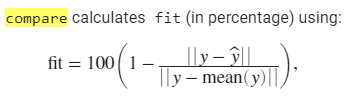

checkModelEstimation = true;    checkLoadingModel = false;

if checkModelEstimation && ~checkLoadingModel
    % Ordine dei modelli
    order_joint1 = 3;
    order_joint2 = 5;

    % opzioni per il fitting del modello
    opts = ssestOptions('EnforceStability',1);

    if (joint1)
        % Selezione range frequenziale su cui fittare il modello
        w_inf = 20;    w_sup = 400;
        freq_range = [find(freq_resp_ident_joint1.Frequency>w_inf & freq_resp_ident_joint1.Frequency<w_sup)];
        region = fselect(freq_resp_ident_joint1,freq_range);

        % Fitting automatico modello continuo e discreto
        modelC_joint1 = ssest(region,order_joint1);
        modelD_joint1 = ssest(region,order_joint1,'Ts',st);

        % Fitting manuale modello continuo e discreto del 3°ordine
        %{
        gain = -35;
        M_Rp_val = 8;       M_Rz_val = 8;
        w_h_val = 6;
        w_Rp_val = 250;     w_Rz_val = 80;
        modelC_joint1 = fit_3order_model(gain,M_Rp_val,M_Rz_val,w_h_val,w_Rp_val,w_Rz_val);
        modelD_joint1 = c2d(modelC_joint1,st);
        %}

        % Quantificazione bontà del fitting
        id_points_joint1 = reshape(abs(freq_resp_ident_joint1.ResponseData),1,[]);
        modelC_points_joint1 = reshape(abs(freqresp(modelC_joint1,freq_resp_ident_joint1.Frequency)),1,[]);
        modelD_points_joint1 = reshape(abs(freqresp(modelD_joint1,freq_resp_ident_joint1.Frequency)),1,[]);
        
        fitC_joint1 = compute_fit_goodness(id_points_joint1,modelC_points_joint1, ...
                                           freq_resp_ident_joint1.Frequency,w_inf,w_sup);
        fitD_joint1 = compute_fit_goodness(id_points_joint1,modelD_points_joint1, ...
                                           freq_resp_ident_joint1.Frequency,w_inf,w_sup);
    end

    if (joint2)
        % Selezione range frequenziale su cui fittare il modello
        w_inf = 20;    w_sup = 700;
        freq_range = [find(freq_resp_ident_joint2.Frequency>w_inf & freq_resp_ident_joint2.Frequency<w_sup)];
        region = fselect(freq_resp_ident_joint2,freq_range);

        % Fitting automatico modello continuo e discreto
        modelC_joint2 = ssest(region,order_joint2);
        modelD_joint2 = ssest(region,order_joint2,'Ts',st);

        % Fitting manuale modello continuo e discreto del 5°ordine
        %{
        gain = -25;
        M_Rp1_val = 14;      M_Rz1_val = 7;
        M_Rp2_val = 8;       M_Rz2_val = 9;
        w_h_val = 10;
        w_Rp1_val = 255;     w_Rz1_val = 160;
        w_Rp2_val = 420;     w_Rz2_val = 330;
        modelC_joint2 = fit_5order_model(gain,M_Rp1_val,M_Rz1_val,M_Rp2_val,M_Rz2_val, ...
                                         w_h_val,w_Rp1_val,w_Rz1_val,w_Rp2_val,w_Rz2_val);
        modelD_joint2 = c2d(modelC_joint2,st);
        %}

        % Fitting manuale modello continuo e discreto del 3°ordine
        %{
        gain = -27;
        M_Rp_val = 18;       M_Rz_val = 18;
        w_h_val = 7;
        w_Rp_val = 260;      w_Rz_val = 120;
        modelC_joint2 = fit_3order_model(gain,M_Rp_val,M_Rz_val,w_h_val,w_Rp_val,w_Rz_val);
        modelD_joint2 = c2d(modelC_joint2,st);
        %}

        % Quantificazione bontà del fitting
        id_points_joint2 = reshape(abs(freq_resp_ident_joint2.ResponseData),1,[]);
        modelC_points_joint2 = reshape(abs(freqresp(modelC_joint2,freq_resp_ident_joint2.Frequency)),1,[]);
        modelD_points_joint2 = reshape(abs(freqresp(modelD_joint2,freq_resp_ident_joint2.Frequency)),1,[]);
        
        fitC_joint2 = compute_fit_goodness(id_points_joint2,modelC_points_joint2, ...
                                           freq_resp_ident_joint2.Frequency,w_inf,w_sup);
        fitD_joint2 = compute_fit_goodness(id_points_joint2,modelD_points_joint2, ...
                                           freq_resp_ident_joint2.Frequency,w_inf,w_sup);
    end

elseif checkLoadingModel && ~checkModelEstimation
    load(directoryModel)

else
    error('Selezionare una delle due opzioni.')
end

## Grafico dei modelli

I dati sperimentali e i modelli stimati sono plottati con l'intervallo di confidenza pari a $3\sigma$.

### Giunto 1

if (joint1)
    fig_j1 = figure;
    h = bodeplot(freq_resp_ident_joint1,bode_opts,'-.');   % diagramma di Bode dati sperimentali
    hold on
    showConfidence(h,3)
    bode(modelC_joint1,modelD_joint1,bode_opts)            % diagramma di bode dei modelli stimati
    
    % Range frequenze investigate
    plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
    plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
    plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
    
    grid on
    hold off
    legend({'Identificazione',strcat("Modello continuo (fitness = ",sprintf("%.2f",fitC_joint1),"%)"), ...
           strcat("Modello discreto  (fitness = ",sprintf("%.2f",fitD_joint1),"%)")}, ...
           'Location','southoutside','Orientation','vertical','FontSize',8)

    % Titolo ed etichette assi personalizzate
    axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
    ha = get(axes(3),'title'); ha.String = 'Input: Coppia [Nm] - Output: Velocità [rad/s]';
    ha = get(axes(1),'title'); ha.String = 'Modello stimato e FRF sperimentale - Giunto 1';

    axes(2).YLim = [-180 90]; % settaggio limiti asse Y per la fase
    axes(2).YTick = [-180 -90 0 90];

    h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
    h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
    x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
    x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\identification\CL_model_joint1.emf')
end

### Giunto 2

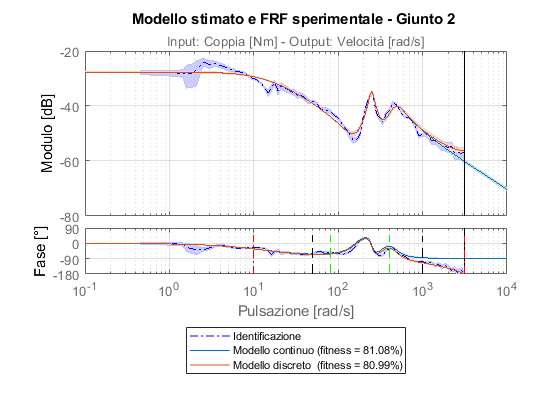

if (joint2)
    fig_j2 = figure;
    h = bodeplot(freq_resp_ident_joint2,bode_opts,'-.');   % diagramma di Bode dati sperimentali
    hold on
    showConfidence(h,3)
    bode(modelC_joint2,modelD_joint2,bode_opts)            % diagramma di bode dei modelli stimati
    
    % Range frequenze investigate
    plot(w0_chirp*[1 1],ylim,'-.r'); plot(w1_chirp*[1 1],ylim,'-.r')
    plot(w0b_chirp*[1 1],ylim,'--g'); plot(w1b_chirp*[1 1],ylim,'--g')
    plot(w0c_chirp*[1 1],ylim,'--k'); plot(w1c_chirp*[1 1],ylim,'--k')
    
    grid on
    hold off
    legend({'Identificazione',strcat("Modello continuo (fitness = ",sprintf("%.2f",fitC_joint2),"%)"), ...
           strcat("Modello discreto  (fitness = ",sprintf("%.2f",fitD_joint2),"%)")}, ...
           'Location','southoutside','Orientation','vertical','FontSize',8)
    
    % Titolo ed etichette assi personalizzate
    axes=findall(gcf,'type','axes');    % (1): plot globale, (2): plot fase, (3): plot modulo
    ha = get(axes(3),'title'); ha.String = 'Input: Coppia [Nm] - Output: Velocità [rad/s]';
    ha = get(axes(1),'title'); ha.String = 'Modello stimato e FRF sperimentale - Giunto 2';

    axes(2).YLim = [-180 90]; % settaggio limiti asse Y per la fase
    axes(2).YTick = [-180 -90 0 90];

    h_magnitude=get(axes(3),'YLabel'); set(h_magnitude,'String','Modulo [dB]')
    h_phase=get(axes(2),'YLabel'); set(h_phase,'String','Fase [°]')
    x_label=get(axes(2),'XLabel'); set(x_label,'String','Pulsazione [rad/s]')
    x_label=get(axes(1),'XLabel'); set(x_label,'String','') % rimuove stringa di default

    % Salvataggio della figura
    set(gcf,'renderer','painters')
    exportgraphics(gcf,'.\presentation\identification\CL_model_joint2.emf')
end

## Salvataggio modello

if checkModelEstimation
    % Salvataggio dati di simulazione
    estimatedModel.simulation = simulation;
    estimatedModel.w_inf = w_inf;                 estimatedModel.w_sup = w_sup;
    estimatedModel.joint1 = joint1;                 estimatedModel.joint2 = joint2;
    estimatedModel.freq_resp_ident_joint1 = [];     estimatedModel.freq_resp_ident_joint2 = [];
    estimatedModel.order_joint1 = order_joint1;     estimatedModel.order_joint2 = order_joint1;
    estimatedModel.modelC_joint1 = [];              estimatedModel.modelD_joint1 = [];
    estimatedModel.modelC_joint2 = [];              estimatedModel.modelD_joint2 = [];
    estimatedModel.fitC_joint1 = [];                estimatedModel.fitD_joint1 = [];
    estimatedModel.fitC_joint2 = [];                estimatedModel.fitD_joint2 = [];
    
    if (joint1)
        estimatedModel.freq_resp_ident_joint1 = freq_resp_ident_joint1;
        estimatedModel.modelC_joint1 = modelC_joint1;    estimatedModel.modelD_joint1 = modelD_joint1;
        estimatedModel.fitC_joint1 = fitC_joint1;        estimatedModel.fitD_joint1 = fitD_joint1;
        
        savefig(fig_j1,strcat(modelFigDirectory,'_j1'))
    end
    
    if (joint2)
        estimatedModel.freq_resp_ident_joint2 = freq_resp_ident_joint2;
        estimatedModel.modelC_joint2 = modelC_joint2;    estimatedModel.modelD_joint2 = modelD_joint2;
        estimatedModel.fitC_joint2 = fitC_joint2;        estimatedModel.fitD_joint2 = fitD_joint2;
        
        savefig(fig_j2,strcat(modelFigDirectory,'_j2'))
    end
    
    save(directoryModel,'-struct','estimatedModel')    
end